# 

# **Simple Linear Regression**

Fit a line to the following data:

`x = [3 4 5 7 8 9 11 12]';`

`y = [6.9 10.0 11.1 15.0 15.7 16.2 24.0 27.5]';`

Determine the $r^2$ and $s_{\frac{y}{x}}$.  

Use the least-squares fit to predict the value of y when x = 6.

Rounding a decimal number to four decimal places.

$r^2$ = ?

$s_{\frac{y}{x}}$ = ?

x = 6, y = ?

**Data**

x = [3 4 5 7 8 9 11 12]';

y = [6.9 10.0 11.1 15.0 15.7 16.2 24.0 27.5]';

**Plot data**

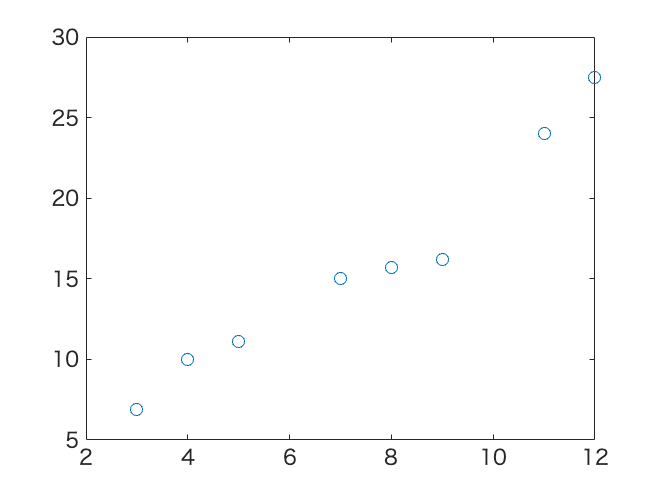

plot(x, y, 'o')

**Calculate polynomial regression using  **`polyfit`**  function**

% p(1) = slope
% p(2) = intercept
p = polyfit(x, y, 1) % n (degree) = 1

p =     2.0900    0.3861


**Plot data and the best fitted curve**

xp = linspace(min(x), max(x), 100)

xp =     3.0000    3.0909    3.1818    3.2727    3.3636    3.4545    3.5455    3.6364    3.7273    3.8182    3.9091    4.0000    4.0909    4.1818    4.2727    4.3636    4.4545    4.5455    4.6364    4.7273    4.8182    4.9091    5.0000    5.0909    5.1818    5.2727    5.3636    5.4545    5.5455    5.6364    5.7273    5.8182    5.9091    6.0000    6.0909    6.1818    6.2727    6.3636    6.4545    6.5455    6.6364    6.7273    6.8182    6.9091    7.0000    7.0909    7.1818    7.2727    7.3636    7.4545


yp = polyval(p, xp)

yp =     6.6562    6.8462    7.0362    7.2262    7.4162    7.6062    7.7962    7.9862    8.1762    8.3662    8.5562    8.7462    8.9362    9.1262    9.3162    9.5062    9.6962    9.8862   10.0762   10.2662   10.4562   10.6462   10.8362   11.0262   11.2162   11.4062   11.5962   11.7862   11.9762   12.1662   12.3562   12.5462   12.7362   12.9262   13.1162   13.3062   13.4962   13.6862   13.8762   14.0662   14.2562   14.4462   14.6362   14.8262   15.0162   15.2062   15.3962   15.5862   15.7762   15.9663


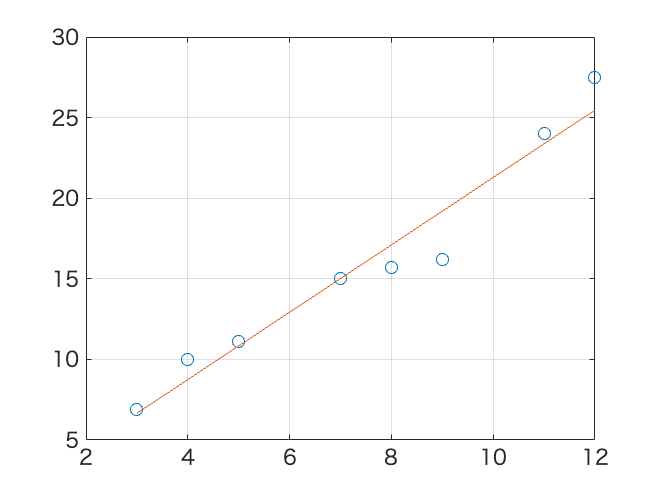

plot(x, y, 'o', xp, yp)
grid on

**Compute  Sr  (the sum of the squares of the residuals between the best-fit curve and the data)**

sr =  sum((y - polyval(p, x)) .^ 2)

sr = 17.1814

**Compute  St   (the sum of the squares of the residuals between the data points and the mean)**

st = sum((y-mean(y)).^2)

st = 339.8800

**Compute  r2  (the coefficient of determination)**

r2 = 1 - (sr/st)

r2 = 0.9494

**Compute  syx  (the standard error of the estimate)  **

syx = sqrt(sr / (length(y) - length(p)))

syx = 1.6922

**Predict the value of y for the given x**

xtest = 6

xtest = 6

ytest = polyval(p, xtest)

ytest = 12.9262